% segment leaves
function result = segment_leaf_watershed(I, info)
    I_rgb = im2double(I);

    %convert image to Lab color space
    I_lab = rgb2lab(I_rgb);
    I_a = I_lab(:,:,2);

    % SLIC
    [L,N] = superpixels(I_lab,3000, IsInputLab=true);
    % get mean intensity a* channel of superpixels L 
    meanColors = regionprops(L, I_a, 'MeanIntensity');
    meanColors = [meanColors.MeanIntensity];
    
    % get foreground by thresholding the mean intensity from the last step 
    threshold = -10;
    plantSuperpixels = find(meanColors < threshold);
    plantMask = ismember(L, plantSuperpixels);
    FG = imoverlay(I_rgb, ~plantMask, "black");
    distanceMap = bwdist(~plantMask);
    TF = islocalmax2(distanceMap, MinProminence=5, MinSeparation=5);
    maxval = distanceMap(TF);
    [row,col]=size(plantMask);
    [X,Y] = meshgrid(1:col,1:row);
    coordinates=[X(TF), Y(TF), maxval];
  
    numel_row = numel(coordinates(:,1));
    markers = zeros(numel_row, 1);
    j = 1;
    for i = 1:numel_row
            x = coordinates(i, 1);
            y = coordinates(i, 2);
            markers(i) = L(y, x);
    end
    maskMarker = ismember(L, markers);
    
    %make the marker/seed bigger
    se_marker = strel('disk',3); 
    plantMask2 = imdilate(plantMask, se_marker);

    I_gmag = imgradient(rgb2gray(I));
    I_gmag2 = imimposemin(I_gmag, ~plantMask2| maskMarker);
    %imshow(imregionalmin(I_gmag2))
    L = watershed(I_gmag2);
    L = L-1;
    imwrite(L, info)
    result = L;
end

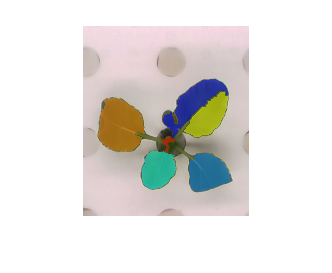

directory = ".\rgbd_plant";
imds = imageDatastore(directory,"FileExtensions", [".jpg",".png"]);
while hasdata(imds)
    [I,info ]= read(imds);
    [folder, baseFile, ext] = fileparts(info.Filename);
    fln = strcat("G:\Documents\Github\Leaf_DIP","/Komatsuna_DIP1/",baseFile, ext);
    i = segment_leaf_watershed(I, fln);
    leafOverlay = labeloverlay(I,i);
    imshow(leafOverlay)  
end